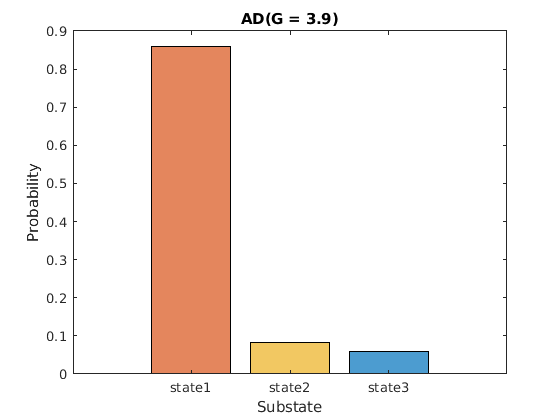

% % 假设 ad_v 是你的6670x1的向量
% % 初始化矩阵来存储每个被试的状态计数
% state_counts = zeros(14, 3);
% 
% % 循环遍历每个被试
% for i = 1:14
%     % 提取当前被试的数据
%     subject_data = hc_v((i-1)*230 + 1:i*230);
%     
%     % 计算1, 2, 3状态的出现次数
%     state_counts(i, 1) = sum(subject_data == 1);
%     state_counts(i, 2) = sum(subject_data == 2);
%     state_counts(i, 3) = sum(subject_data == 3);
% end
% 
% % 计算概率矩阵
% state_pro_hc = state_counts / 230;
% 假设 ad_v 是包含数值的6670x1向量

% 计算数值1, 2, 3的出现次数
% counts = [sum(ad_v == 1), sum(ad_v == 2), sum(ad_v == 3)];
% 
% % 转换次数为概率
% probabilities = counts / length(ad_v);
% 
% % 绘制柱状图
% figure(1)
% bar(1:3, probabilities);
% title('Probability of Each Value (1-3)');
% xlabel('Value');
% ylabel('Probability');
% xticks(1:3);
% figure(2)
% 
% % 计算数值1, 2, 3的出现次数
% counts = [sum(hc_v == 1), sum(hc_v == 2), sum(hc_v == 3)];
% 
% % 转换次数为概率
% probabilities = counts / length(hc_v);
% 
% % 绘制柱状图
% bar(1:3, probabilities);
% title('Probability of Each Value (1-3)');
% xlabel('Value');
% ylabel('Probability');
% xticks(1:3);
% 计算数值1, 2, 3的出现次数
% load ad_idx;
% load hc_idx;
% counts = [sum(ad_v == 1), sum(ad_v == 2), sum(ad_v == 3)];

% 计算数值的概率
% probabilities = counts / length(ad_v);
sim_ad = [0.8582 0.0820 0.0599];
% 绘制柱状图
figure(1)
b = bar(1:3, sim_ad);
title('AD(G = 3.9)');
xlabel('Substate');
ylabel('Probability');
xticks(1:3);
xticklabels({'state1','state2','state3'});
% 设置每个柱子的颜色和透明度
b.FaceColor = 'flat';
b.CData(1,:) = [0.8500 0.3250 0.0980]; % 自定义颜色
b.CData(2,:) = [0.9290 0.6940 0.1250]; % 自定义颜色
b.CData(3,:) = [0 0.4470 0.7410]; % 蓝色
b.FaceAlpha = 0.7; % 设置透明度为50%

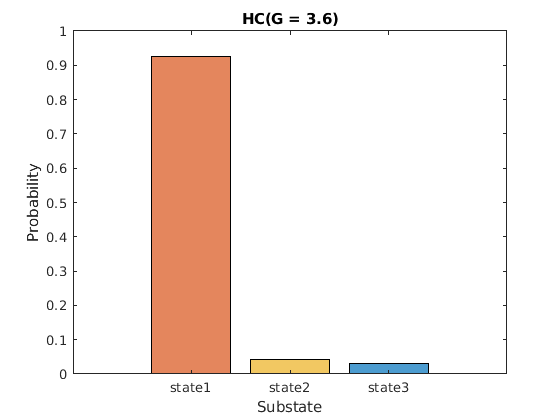


% 假设hc_v是另一个数据集
% 计算数值1, 2, 3的出现次数
% counts = [sum(hc_v == 1), sum(hc_v == 2), sum(hc_v == 3)];

% 计算数值的概率
% probabilities = counts / length(hc_v);
sim_hc = [0.9258 0.0433 0.0309];
% 绘制柱状图
figure(2)
b = bar(1:3, sim_hc);
title('HC(G = 3.6)');
xlabel('Substate');
ylabel('Probability');
xticks(1:3);
xticklabels({'state1','state2','state3'});
% 设置每个柱子的颜色和透明度
b.FaceColor = 'flat';
b.CData(1,:) = [0.8500 0.3250 0.0980]; % 自定义颜色
b.CData(2,:) = [0.9290 0.6940 0.1250]; % 自定义颜色
b.CData(3,:) = [0 0.4470 0.7410]; % 自定义颜色
b.FaceAlpha = 0.7; % 设置透明度为50%